# Lectura de datos

Cargando los datos de la persona 20

load('CIPIC_hrtf_database\standard_hrir_database\subject_020\hrir_final.mat');

Datos de la localizacion de fuente deseada

azimuth=45;     % limite de [-90,90]
elevacion=20;   % limite de [-90,270]

Usando la funcion para optener la respuesta impulsiva izquierda

[pulsol ,azerl, elerl]=getNearestUDCpulse(azimuth,elevacion,hrir_l);

Usando la funcion para optener la respuesta impulsiva derecha

[pulsor ,azerr, elerr]=getNearestUDCpulse(azimuth,elevacion,hrir_r);

grafico de las respuestas impulsivas

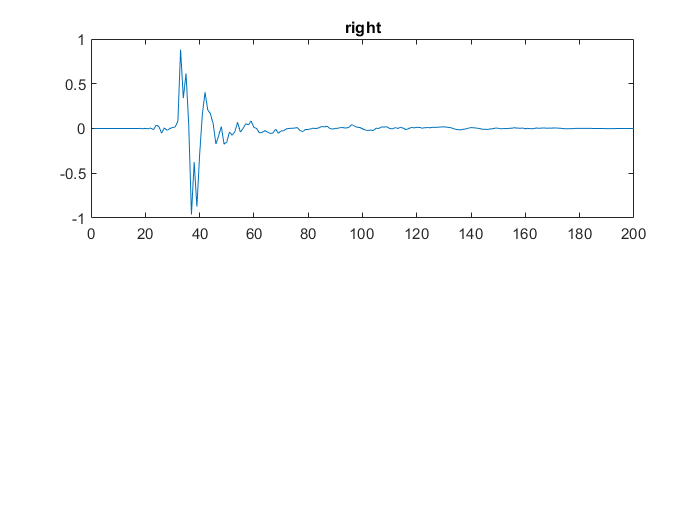

figure(1);
subplot(211);plot(pulsor);title('right');

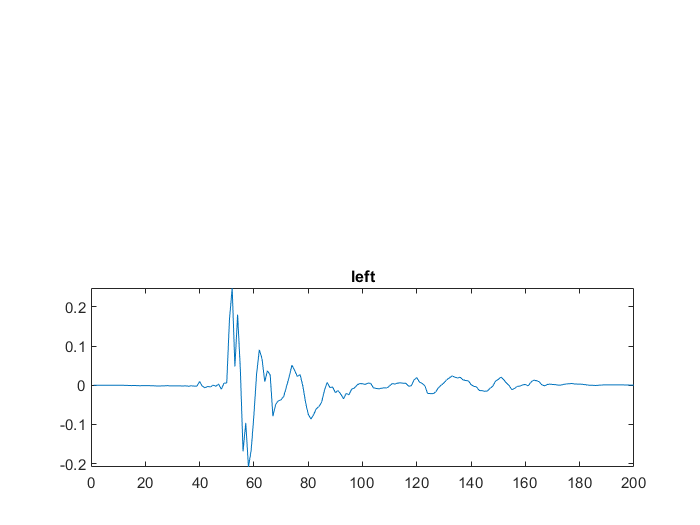

figure(2);
subplot(212);plot(pulsol);title('left');

leer audio de prueba

[y,Fs]=audioread('recorte.mp3');

convolucion para obtener la señal deseada

yr=conv(y(:,1)',pulsor);    %señal derecha
yl=conv(y(:,2)',pulsol);    %señal izquierda

uniendo las pistas y reproduciendo 

% yn=[yl;yr];
% sound(yn,Fs);